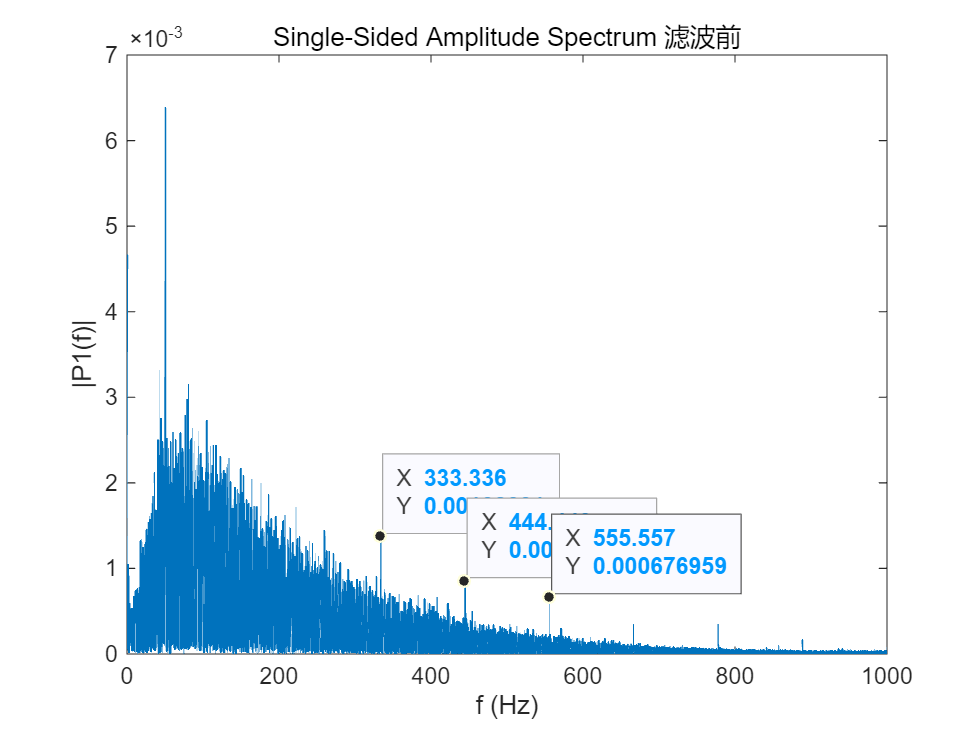

n=31;
gn=2;
% signal=data{gn}(n,:);
signal=EMG(n,:);

clf; %a=plot(signal);
Y=fft(signal);
Fs=2000;L=length(signal);
P2 = abs(Y/L);
P1 = P2(1:(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);f = Fs/L*(0:(L/2));
plot(f,P1,"LineWidth",1) 
title("Single-Sided Amplitude Spectrum 滤波前")
xlabel("f (Hz)")
ylabel("|P1(f)|")




signal=decompData{gn}(n,:);

未定义变量 'decompData'。

clf;%a=plot(signal);
Y=fft(signal);
Fs=2000;L=length(signal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);f = Fs/L*(0:(L/2));
plot(f,P1,"LineWidth",1) 
title("Single-Sided Amplitude Spectrum 滤波后")
xlabel("f (Hz)")
ylabel("|P1(f)|")